% AVD Constraint Diagram Code (corrected)
% Original: Ananjan Pillai, Version 2 (13/10/2026)
%
% Corrections in this version:
%  1. Input CSV is no longer overwritten. Results go to Key_Param_recording_updated.csv.
%  2. Design point is the lowest point on the upper constraint envelope inside the
%     landing limit, found by a fixed-point loop (V_x depends on wing loading).
%     The old tolerance search (abs diff < 0.01) found no match and failed.
%  3. Climb speed at 10,000 ft uses V_climb from the CSV (150 m/s), not M_cruise*a.
%  4. V_x for the ceiling uses rho at the absolute ceiling, not rho at 40,000 ft.
%  5. Removed broken line h_cruise_m = getParam('cruise_alt_ft'*ft2m).
%  6. Parameters are read once from the CSV. getParam errors if a name is missing
%     instead of silently returning empty.
%  7. Legend uses DisplayName, so labels can no longer be attached to the wrong curves.
%  8. Duplicate reads (params/paramTable, e, K) and unused variables removed.
%  9. Cruise and climb lines use the same helper functions, so they cannot drift apart.

clear; clc; close all;

%% ------------------------------------------------------------------------
%% 1. INPUTS
%% ------------------------------------------------------------------------
inFile  = 'Key_Param_recording.csv';
outFile = 'Key_Param_recording.csv';   % input file is left unchanged

opts       = detectImportOptions(inFile);
paramTable = readtable(inFile, opts);
getParam   = @(name) localGetParam(paramTable, name);

% Values from the CSV
AR          = getParam('AR');                       % Aspect ratio
e_oswald    = getParam('Oswald_efficiency_factor'); % Oswald efficiency
CD0         = getParam('CD0');                      % Zero-lift drag coefficient
M_cruise    = getParam('M_cruise');                 % Cruise Mach number
L_runway    = getParam('L_runway');                 % Runway length [m]
W0          = getParam('W_0_guess');                % MTOW from mass iteration [kg]
abs_ceil_ft = getParam('abs_ceiling_ft');           % Absolute ceiling [ft]
Vstall_takeoff = getParam('Vstall_takeoff');                  % Stall speed [m/s]
Vstall_landing = getParam('Vstall_landing');  
V_climb     = getParam('V_climb');                  % Climb speed [m/s]
gamma_req   = getParam('climb_gradient_2nd');       % OEI climb gradient (2.4%)
Wr_to       = getParam('Wr_taxi_takeoff');          % Weight fraction taxi & takeoff
Wr_clb      = getParam('Wr_climb');                 % Weight fraction climb
Wr_cruise = getParam('Wr_cruise');
S_ref_csv   = getParam('S_ref');                    % Starting wing area [m^2]

% Manual values (not in CSV, or differ from CSV, kept as in original)
g          = 9.81;
ft2m       = 0.3048;
sigma_to   = 1.0;      % density ratio for sea level
K_R        = 1.0;      % runway correction factor
Sa         = 305;      % air distance safety margin [m]
CLmax_L    = 2.80;     % landing CL_max (slide 23).
CLmax_TO   = 2.2;      % take-off CL_max
CL_LOF     = 0.8*CLmax_TO;
NE         = 2;        % number of engines
alpha_to   = 1.0;      % take-off weight ratio
alpha_cr   = Wr_to*Wr_clb;     % cruise weight ratio (0.97*0.985)
alpha_ceil = alpha_cr*0.7133;   % weight ratio at absolute ceiling
beta_cr    = 0.23;     % thrust lapse, cruise (slide 12)
beta_30k   = 0.30;     % thrust lapse, 30,000 ft line
beta_40k   = 0.20;     % thrust lapse, 40,000 ft line
beta_ceil  = 0.20;     % thrust lapse, absolute ceiling

K_induced  = 1/(pi*AR*e_oswald);   % induced drag factor

%% ------------------------------------------------------------------------
%% 2. WING LOADING GRID AND LIMITS
%% ------------------------------------------------------------------------
N_WS = 8000;
WS   = linspace(500, 9000, N_WS);  % wing loading [N/m^2]

ALD_max         = 0.60*L_runway;
WS_landing_limit = (ALD_max - Sa)*sigma_to*CLmax_L/(0.51*K_R);   % check vs slide

%% ------------------------------------------------------------------------
%% 3. CONSTRAINT CURVES (T/W against W/S)
%% ------------------------------------------------------------------------
% Take-off (Raymer take-off parameter)
TOP_req    = L_runway/(0.297 - 0.019*NE);
TW_takeoff = (WS/(sigma_to*CL_LOF*TOP_req))/alpha_to;

% OEI climb (constant in W/S)
TW_climb2     = (NE/(NE-1))*(gamma_req + 2*sqrt(CD0*K_induced));
TW_climb2_vec = TW_climb2*ones(size(WS));

% Absolute ceiling: V_x evaluated at ceiling density (updated in the solver below)
h_ceil_m       = abs_ceil_ft*ft2m;
[~, ~, ~, rho_ceil] = atmosisa(h_ceil_m);

% Cruise lines
TW_30k = cruiseTW(WS, 30000, beta_30k, alpha_cr, M_cruise, CD0, K_induced, ft2m);
TW_37k = cruiseTW(WS, 37000, beta_cr,  alpha_cr, M_cruise, CD0, K_induced, ft2m);
TW_40k = cruiseTW(WS, 40000, beta_40k, alpha_cr, M_cruise, CD0, K_induced, ft2m);

% Climb lines
TW_c10_3000 = climbTW(WS, 10000, 3000, V_climb, 0.85,    alpha_cr, CD0, K_induced, ft2m);
TW_c10_1500 = climbTW(WS, 10000, 1500, V_climb, 0.85,    alpha_cr, CD0, K_induced, ft2m);
[~, a_cruise, ~, ~] = atmosisa(37000*ft2m);
V_c37k      = M_cruise*a_cruise;                              % estimated TAS at 37,000 ft
TW_c37k     = climbTW(WS, 37000,  500, V_c37k, beta_cr,  alpha_cr, CD0, K_induced, ft2m);

%% ------------------------------------------------------------------------
%% 4. DESIGN POINT
%% ------------------------------------------------------------------------
% Design point = lowest T/W on the upper envelope of all constraints, with W/S
% inside the landing limit. The ceiling curve depends on V_x, which depends on
% W/S, so iterate until the design W/S stops changing.

ws   = g*W0/S_ref_csv;     % starting guess from current wing area
tolWS   = 0.1;            % convergence tolerance [N/m^2]
maxIter = 100;
converged = false;

for k = 1:maxIter
    V_ceil = sqrt(2*ws/rho_ceil)*(K_induced/CD0)^(1/4);   % best-climb speed at ceiling
    q_ceil = 0.5*rho_ceil*V_ceil^2;
    TW_ceil = (alpha_ceil/beta_ceil)*((q_ceil*CD0./WS) + (WS/q_ceil)*K_induced);

    TW_env = max([TW_takeoff; TW_ceil; TW_climb2_vec; TW_30k; TW_37k; TW_40k; ...
                  TW_c10_3000; TW_c10_1500; TW_c37k]);

    TW_env_feas = TW_env;
    TW_env_feas(WS > WS_landing_limit) = Inf;
    [TW_design, iDes] = min(TW_env_feas);
    ws_new = WS(iDes);

    if abs(ws_new - ws) < tolWS
        ws = ws_new;
        converged = true;
        break
    end
    ws = ws_new;
end

if ~converged
    warning('Design point did not converge after %d iterations.', maxIter);
end

% Derived outputs
V_x_out = V_ceil;                      % best-climb speed at ceiling for the design W/S
S_ref_out = g*W0/ws;                   % wing reference area [m^2]

fprintf('\n--- Design point ---\n');


--- Design point ---


fprintf('Wing loading W/S        : %.1f N/m^2\n', ws);

Wing loading W/S        : 6082.0 N/m^2


fprintf('Thrust-to-weight T/W    : %.4f\n', TW_design);

Thrust-to-weight T/W    : 0.2983


fprintf('Wing reference area S   : %.2f m^2 (CSV had %.2f)\n', S_ref_out, S_ref_csv);

Wing reference area S   : 469.95 m^2 (CSV had 469.95)


fprintf('Best-climb speed V_x    : %.2f m/s\n', V_x_out);

Best-climb speed V_x    : 270.54 m/s


if ws <= WS_landing_limit, lim_txt = 'inside'; else, lim_txt = 'OUTSIDE'; end
fprintf('Landing limit W/S       : %.1f N/m^2 (design is %s)\n', WS_landing_limit, lim_txt);

Landing limit W/S       : 8207.8 N/m^2 (design is inside)


fprintf('Converged               : %d\n', converged);

Converged               : 1



%% ------------------------------------------------------------------------
%% 5. SAVE RESULTS (copy of CSV; input file untouched)
%% ------------------------------------------------------------------------
paramOut = paramTable;
updates  = {'Wing_loading', ws; ...
            'Thrust_to_weight', TW_design; ...
            'S_ref', S_ref_out; ...
            'V_x', V_x_out};
for r = 1:size(updates, 1)
    idx = strcmp(paramOut.Parameter, updates{r,1});
    if ~any(idx)
        error('Output parameter "%s" not found in CSV.', updates{r,1});
    end
    paramOut.Value(idx) = updates{r,2};
end
writetable(paramOut, outFile);
fprintf('Saved results to %s\n', outFile);

Saved results to Key_Param_recording.csv


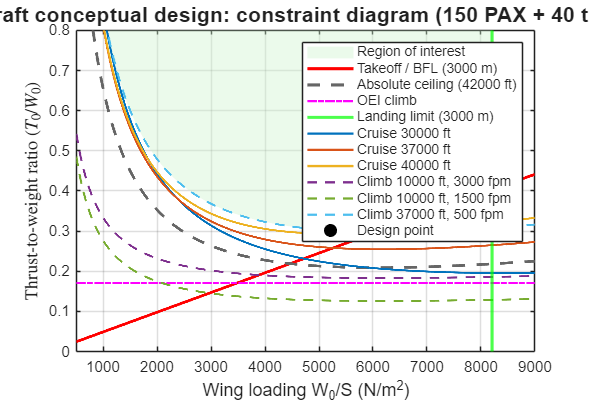


%% ------------------------------------------------------------------------
%% 6. PLOT
%% ------------------------------------------------------------------------
figure('Name', 'Aircraft Constraint Diagram', 'Color', 'white', 'Position', [100 100 950 650]);
hold on; grid on; box on;

% Feasible region: above the upper envelope, left of the landing limit
WS_feas = WS(WS <= WS_landing_limit);
TW_upper = TW_env(WS <= WS_landing_limit);
fill([WS_feas, fliplr(WS_feas)], [TW_upper, 0.8*ones(size(WS_feas))], [0.8 0.95 0.8], ...
     'EdgeColor', 'none', 'FaceAlpha', 0.4, 'DisplayName', 'Region of interest');

plot(WS, TW_takeoff, 'r-', 'LineWidth', 2, 'DisplayName', 'Takeoff / BFL (3000 m)');
plot(WS, TW_ceil, 'Color', [0.4 0.4 0.4], 'LineWidth', 2, 'LineStyle', '--', ...
     'DisplayName', 'Absolute ceiling (42000 ft)');
plot(WS, TW_climb2_vec, 'm-.', 'LineWidth', 1.5, 'DisplayName', 'OEI climb');
xline(WS_landing_limit, 'g-', 'LineWidth', 2, 'DisplayName', 'Landing limit (3000 m)');
plot(WS, TW_30k, 'Color', [0 0.447 0.741], 'LineWidth', 1.5, 'DisplayName', 'Cruise 30000 ft');
plot(WS, TW_37k, 'Color', [0.85 0.325 0.098], 'LineWidth', 1.5, 'DisplayName', 'Cruise 37000 ft');
plot(WS, TW_40k, 'Color', [0.929 0.694 0.125], 'LineWidth', 1.5, 'DisplayName', 'Cruise 40000 ft');
plot(WS, TW_c10_3000, 'LineStyle', '--', 'Color', [0.494 0.184 0.556], 'LineWidth', 1.5, ...
     'DisplayName', 'Climb 10000 ft, 3000 fpm');
plot(WS, TW_c10_1500, 'LineStyle', '--', 'Color', [0.466 0.674 0.188], 'LineWidth', 1.5, ...
     'DisplayName', 'Climb 10000 ft, 1500 fpm');
plot(WS, TW_c37k, 'LineStyle', '--', 'Color', [0.301 0.745 0.933], 'LineWidth', 1.5, ...
     'DisplayName', 'Climb 37000 ft, 500 fpm');
plot(ws, TW_design, 'ko', 'MarkerFaceColor', 'k', 'MarkerSize', 8, ...
     'DisplayName', 'Design point');

xlabel('Wing loading W_0/S (N/m^2)', 'FontSize', 12);
ylabel('Thrust-to-weight ratio $(T_0/W_0)$', 'Interpreter', 'latex', 'FontSize', 12);
title('Aircraft conceptual design: constraint diagram (150 PAX + 40 t cargo)', ...
      'FontSize', 14);
axis([500 9000 0 0.8]);
legend('Location', 'northeast', 'Interpreter', 'none');


%% ========================================================================
%% LOCAL FUNCTIONS
%% ========================================================================
function v = localGetParam(T, name)
    idx = strcmp(T.Parameter, name);
    if ~any(idx)
        error('Parameter "%s" not found in CSV.', name);
    end
    v = T.Value(find(idx, 1));
end

function TW = cruiseTW(WS, alt_ft, beta, alpha, M, CD0, K, ft2m)
    [~, a, ~, rho] = atmosisa(alt_ft*ft2m);
    q  = 0.5*rho*(M*a)^2;
    TW = (alpha/beta)*((q*CD0./WS) + (WS/q)*K);
end

function TW = climbTW(WS, alt_ft, roc_fpm, V, beta, alpha, CD0, K, ft2m)
    [~, ~, ~, rho] = atmosisa(alt_ft*ft2m);
    q  = 0.5*rho*V^2;
    gamma_term = (roc_fpm*0.00508)/V;      % ROC [m/s] / V
    TW = (alpha/beta)*(gamma_term + (q*CD0./WS) + (WS/q)*K);
end